# M4T2: Regresión lineal / polinomial

`Nombre: Daniel Alfredo Barreras Meraz`

`Matrícula: A01254805`

`Fecha: 5 de junio de 2023`

## Problema a: Población 

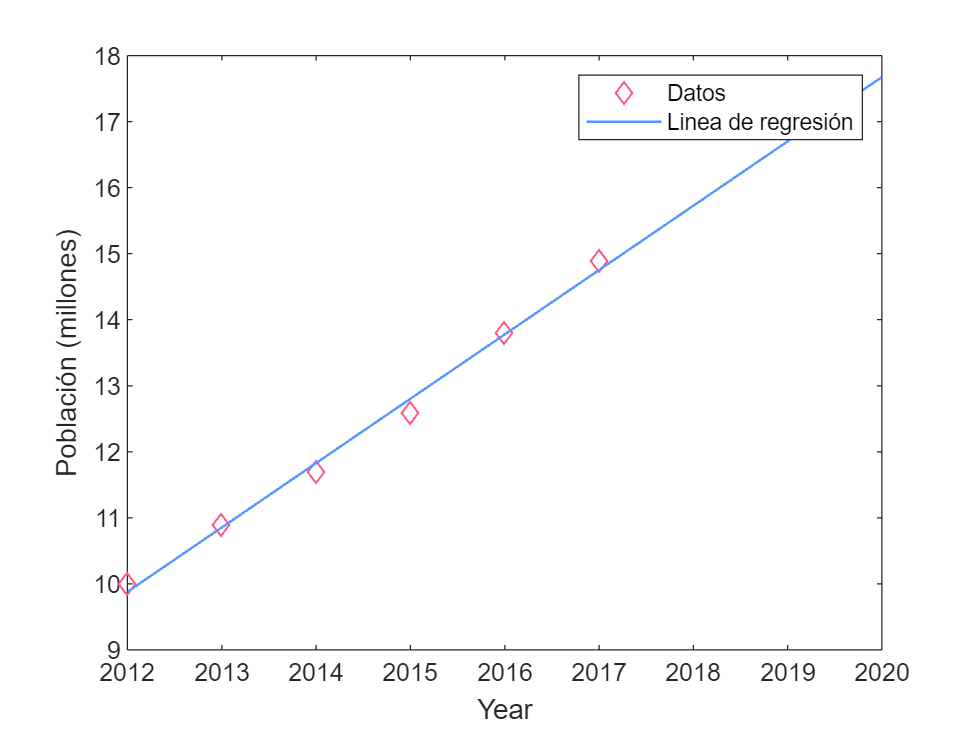

% Datos sobre la población
x = [2012 2013 2014 2015 2016 2017];
y = [10 10.9 11.7 12.6 13.8 14.9];

% Linea de regresión
[a, b] = minimosCuadrados(x, y);

% Muestra la tabla y la linea de regresión
xfit = linspace(2012, 2020);
yfit = a * xfit + b;
plot(x, y, 'dk', 'color', '#ff5688', 'LineWidth', 0.96);
hold on;
plot(xfit, yfit, 'color', '#5896ff', 'LineWidth', 0.96);
hold off;
xlabel('Year')
ylabel('Población (millones)')
legend('Datos', 'Linea de regresión')

% Estima el año en que la población seré el doble de lo que fue en 2014
pop2014 = a * 2014 + b;
popDouble = 2 * pop2014;
yearDouble = (popDouble - b) / a;
disp(['La población será el doble de lo que fue en 2014 en el año: ' num2str(yearDouble)])

La población será el doble de lo que fue en 2014 en el año: 2026.1417


## Problema b: Solubilidad de la sal en agua

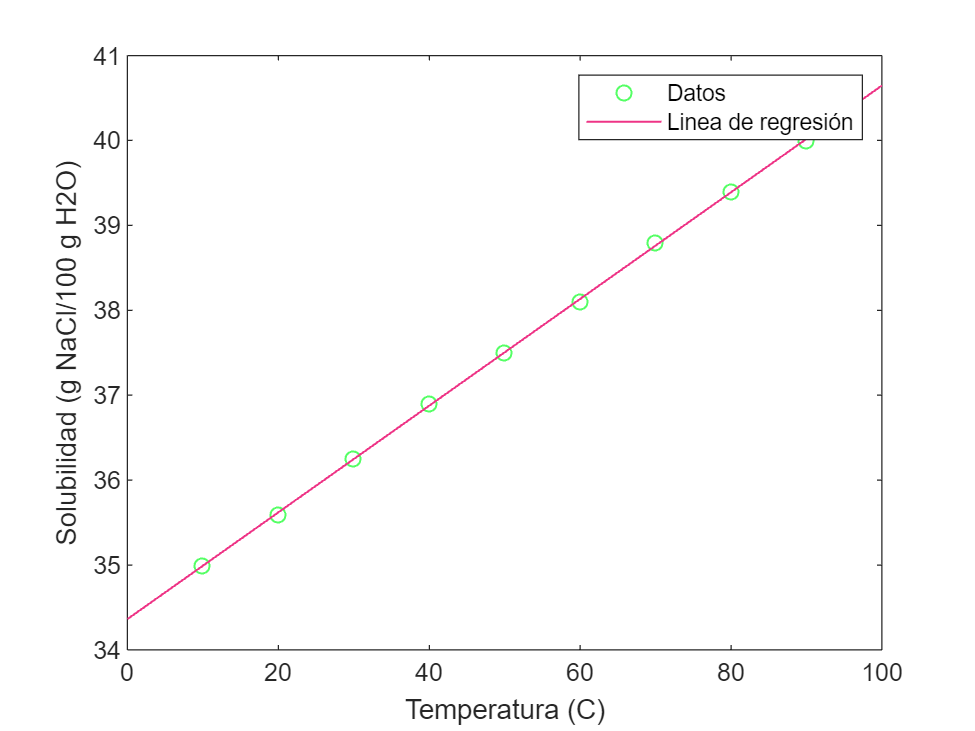

% Datos sobre la solubilidad
T = [10 20 30 40 50 60 70 80 90];
S = [35 35.6 36.25 36.9 37.5 38.1 38.8 39.4 40];

% Encontrar la linea de regresión
[a, b] = minimosCuadrados(T, S);

% Muestra la grafica y la línea de regresión
Tfit = linspace(0, 100);
Sfit = a * Tfit + b;
plot(T, S, 'o', 'color', '#55ff65', 'LineWidth', 0.8);
hold on;
plot(Tfit, Sfit, 'color', "#ee3486", 'LineWidth', 0.8);
hold off;
xlabel('Temperatura (C)')
ylabel('Solubilidad (g NaCl/100 g H2O)')
legend('Datos', 'Linea de regresión')


% Estimar la solubilidad cuando la temperatura es 25C
S_25C = a * 25 + b;
disp(['La solubilidad cuando la temperatura es 25ºC es: ' num2str(S_25C) ' g NaCl/100 g H2O'])

La solubilidad cuando la temperatura es 25ºC es: 35.9347 g NaCl/100 g H2O


## Función que implementa el método numérico de Mínimos cuadrados

function [a, b] = minimosCuadrados(x, y)
    x_mean = mean(x);
    y_mean = mean(y);
    xy_mean = mean(x.*y);
    x_squared_mean = mean(x.^2);
    a = (x_mean * y_mean - xy_mean) / (x_mean^2 - x_squared_mean);
    b = y_mean - a * x_mean;
end